clear
load('sensorlog_20230608_121004.mat');
lat=Position.latitude;
lon=Position.longitude;
positionDatetime=Position.Timestamp;

Xacc = Acceleration.X;
Yacc = Acceleration.Y;
Zacc = Acceleration.Z;
accelDatetime=Acceleration.Timestamp;

positionTime=Position.Timestamp;


% We use the following to obtain linear time data in seconds from a datetime array
positionTime=timeElapsed(positionTime)

positionTime =          0
    9.0260
   10.0260
   11.0260
   12.0260
   13.0260
   14.0260
   15.0260
   16.0260
   17.0260


steps

earthCirc=24901;
totaldis=0;
stride=2.5;

for i = 1: (length(lat)-1)
    lat1 = lat(i); %This represents the first latitude
    lat2 = lat(i+1); %This will be the second latitude
    lon1 = lon(i);
    lon2 = lon(i+1);
    diff = distance(lat1, lon1, lat2, lon2);
    dis = (diff/360)*earthCirc;
    totaldis = totaldis +dis;
    totaldis_ft=totaldis*5280; %convert to feet
     
end     

calories

cal_per_step=0.05;
steps=round(totaldis_ft/stride);
calories=cal_per_step*steps;
    


diag

accelTime=Acceleration.Timestamp;
accelTime=timeElapsed(accelTime)

accelTime =          0
    0.0180
    0.0360
    0.0540
    0.0720
    0.0900
    0.1080
    0.1260
    0.1440
    0.1620


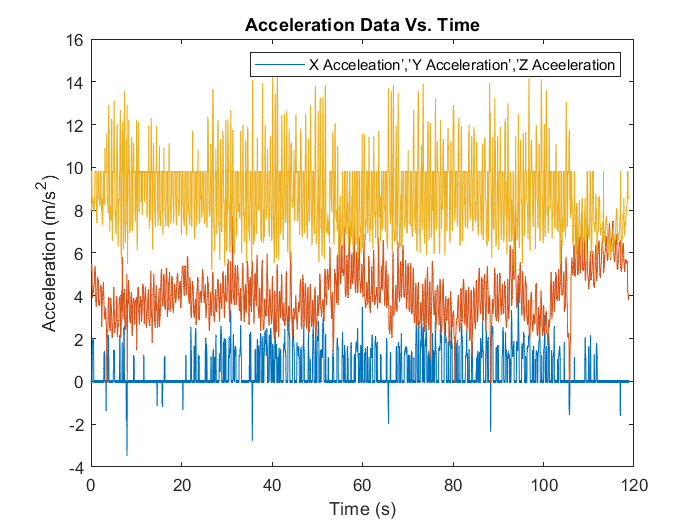

plot(accelTime,Acceleration.X);
hold on;
plot(accelTime,Acceleration.Y);
plot(accelTime,Acceleration.Z)
legend("X Acceleation’,’Y Acceleration’,’Z Aceeleration");
xlabel("Time (s)")
ylabel("Acceleration (m/s^2)");
title("Acceleration Data Vs. Time");
hold off

flights of stairs climbed

steps_per_flight = 10; % Number of steps per flight

floors=round(steps/steps_per_flight);

mets

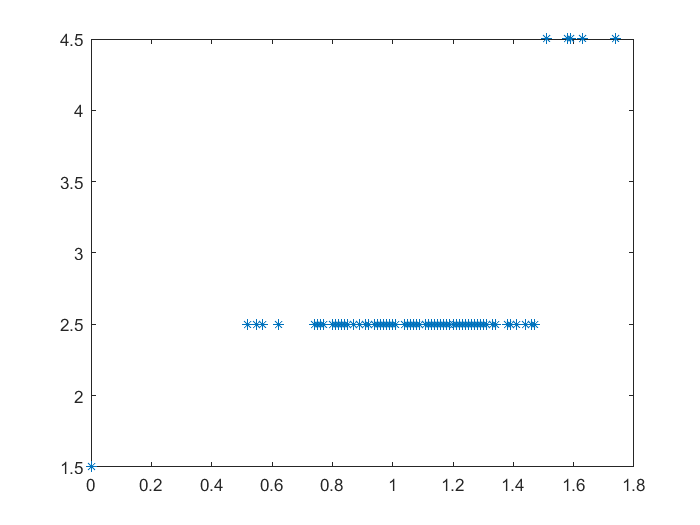

met=zeros(1,length(lat));
for i = 1:length(lat)
    if Position.speed(i) < 0.4
        met(i) = 1.5; % Assigning MET value less than 1.5
    elseif (Position.speed(i) >= 0.4) && (Position.speed(i) < 1.5)
        met(i) = 2.5; % Assigning MET value between 1.5 and 3
    elseif (Position.speed(i) >= 1.5) && (Position.speed(i) < 2)
        met(i) = 4.5; % Assigning MET value between 3 and 6
    else
        met(i) = 8; % Assigning MET value greater than 6
    end
end
plot(Position.speed,met,"*")

function

function newArray = timeElapsed(datetime_array)
    % This function converts an array of elements in datetime format
    % into the total elapsed time in seconds since the first data point was
    % acquired
    %
    % To find out more about datetime formats and arrays try the command:
    %
    %   >> doc datetime
    %
    % Copyright 2018 The MathWorks, Inc
    
    newArray = second(datetime_array);
    arraySize = numel(newArray); % Number of elements in the array
    first = newArray(1);
    i = 1;
    
    % The following loop will run until it reaches the end of the array.
    % Whenever the next number is smaller than the current number the loop will
    % add 60 seconds and then start at the begining of the array again.
    while i < arraySize
        if newArray(i) > newArray(i+1)
            newArray(i+1) = newArray(i+1) +60;
            i = 1;
        end
        i = i+1;
    end
    
    % Subtract the first number to all elements of the array in order to start
    % the array at 0.
        newArray = newArray - first;  
end